# Péndulo - Nonlinear model

[http://www.sc.ehu.es/sbweb/fisica/dinamica/trabajo/pendulo/pendulo.htm](http://www.sc.ehu.es/sbweb/fisica/dinamica/trabajo/pendulo/pendulo.htm)

Un péndulo simple se define como una partícula (bob) de masa *m* suspendida del punto O por un hilo inextensible de longitud *l* y de masa despreciable.

Si la partícula se desplaza a una posición $\theta_0$ (ángulo que hace el hilo con la vertical) y luego se suelta, el péndulo comienza a oscilar.

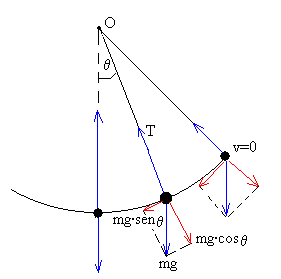

## Ecuación del movimiento en la dirección tangencial (sin fricción)

La aceleración de la partícula es $a_{t\;} =\frac{\mathrm{d}}{\mathrm{d}t}v$ 

La segunda ley de Newton se escribe $m\;a_t =-m\;g\;\textrm{sen}\;\theta$   (fuerza de restauración)

La relación entre la aceleración tangencial y la aceleración angular es $a_t =\alpha \;l$ 

La ecuación del movimiento se escribe en forma de ecuación diferencial


$$\alpha \;l=-g\;\mathrm{sen}\;\theta$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta =-\frac{g}{l}\;\textrm{sen}\;\theta$$


 
$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta +\frac{g}{l}\;\textrm{sen}\;\theta =0$$


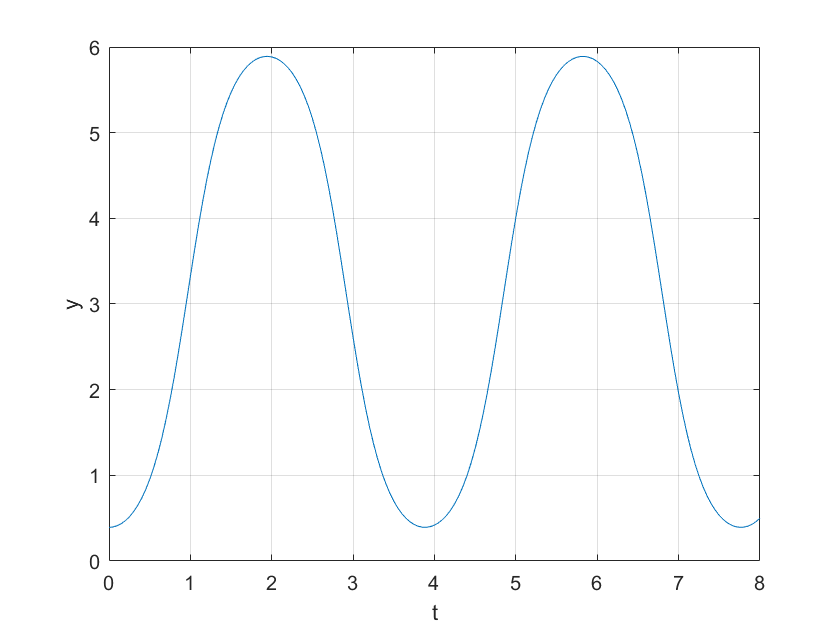

g = 9.81;
l = 1;

% theta'' = g/l * sen(theta)
% theta' = omega
% omega' = theta'' = g/l * sen(theta)
% y = [theta;omega]

t0 = 0;
h = 0.05;
y0 = [pi/8; 0];
T = 2*pi*sqrt(l/g);
tf = 4*T;

f = @(t,y) [y(2);g/l*sin(y(1))];
[t,y] = ivpsV(f, y0, t0, tf, h, 'rk4');
plot(t,y(1,:));
xlabel('t');
ylabel('y');
grid on;

## Energy analysis

The kinetic energy possessed by an object is the energy it possesses due to its motion. It is a quantity that depends upon both mass and speed. The equation that  relates kinetic energy (KE) to mass (m) and speed (v) is


$$\textrm{KE}=\frac{1}{2}mv^2$$


The faster an object moves, the more kinetic energy that it will possess. 

The potential energy possessed by an object is the stored energy of position. The amount of gravitational potential energy is dependent upon the mass (m) of the object and the height (h) of the object. The equation for gravitational potential energy (PE) is


$$\textrm{PE}=m\;g\;h$$


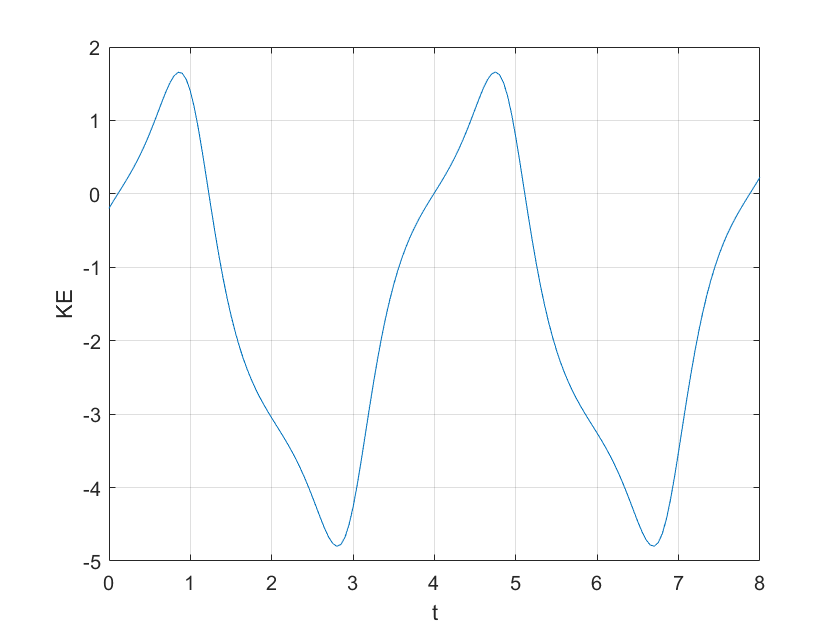

% m=1, como estamos comparando, m no importa
m=1;
KE=m*diff(y)/2;
plot(t,KE(1,:))
xlabel('t');
ylabel('KE');
grid on;

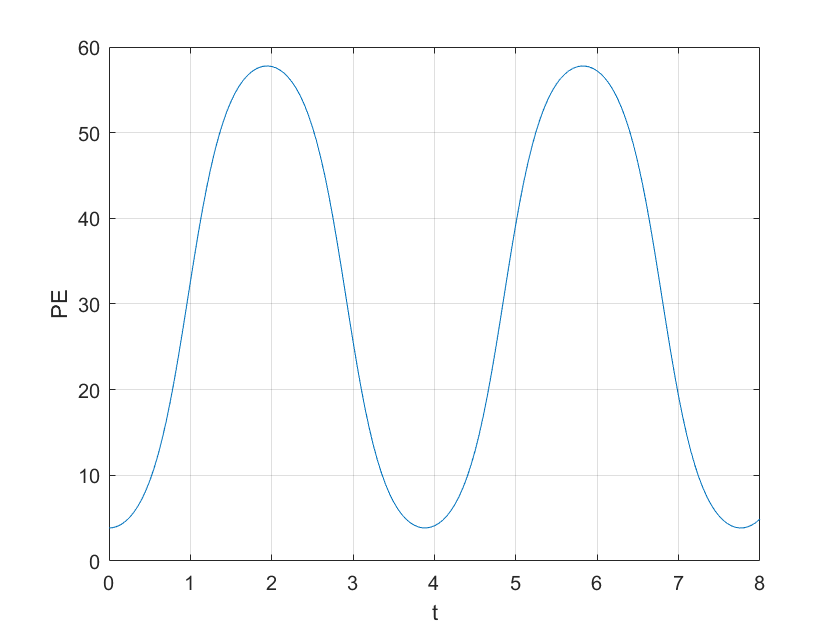

PE=m*g*y;
plot(t,PE(1,:))
xlabel('t');
ylabel('PE');
grid on;

## Solución analítica

syms y(t) g l theta0

ode = diff(y,t,2)+ g/l * sin(y) == 0;
yG=dsolve(ode)

$$yG = \left(\begin{array}{c} 0\\ 2\,\mathrm{am}\left(\frac{\sqrt{2}\,\sqrt{C_{1}-g}\,\left(C_{2}-t\right)\,\mathrm{i}}{2\,\sqrt{l}}|-\frac{2\,g}{C_{1}-g}\right)\\ -2\,\mathrm{am}\left(\frac{\sqrt{2}\,\sqrt{C_{1}-g}\,\left(C_{2}-t\right)\,\mathrm{i}}{2\,\sqrt{l}}|-\frac{2\,g}{C_{1}-g}\right) \end{array}\right)$$

y0 = [pi/8; 0];
cond1 = y(0) == y0(1);
Dy=diff(y);
cond2 = Dy(0) == y0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

 
yP =
 
[ empty sym ]
 


function [x,y] = ivpsV( f, y0, x0, xf, h, method)
    x= x0:h:xf;
    n=length(x);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    
    for i=1:1:n-1
        switch method
        case 'euler'
            phi=f(x(i),y(:,i));
            y(:,i+1)=y(:,i)+phi*h;
        case 'midpoint'
            ymid=y(i)+f(x(i),y(:,i))*h/2;
            phi=f(x(i)+h/2,ymid);
            y(:,i+1)=y(:,i)+phi*h;
        case 'heun'
            s1=f(x(i),y(:,i));
            predictor=y(:,i)+s1*h;
            s2= f(x(i+1), predictor);
            phi = (s1+s2)/2;
            y(:,i+1)=y(:,i)+phi*h;
        case 'rk4'
            k1=f(x(i),y(:,i));
            k2=f(x(i)+h/2,y(:,i)+k1*h/2);
            k3=f(x(i)+h/2,y(:,i)+k2*h/2);
            k4=f(x(i)+h, y(:,i)+k3*h);
            y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
        end
    end
end